clear, clc

veh = veh_params();
track_name = char("Catalunya");

## A. Track Smoothing

% track = readtable(['tracks\' track_name '.csv'], 'PreserveVariableNames',true);
track_path = ['..\racetrack-database\tracks\' track_name '.csv'];

track_path = '..\racetrack-database\tracks\Catalunya.csv'

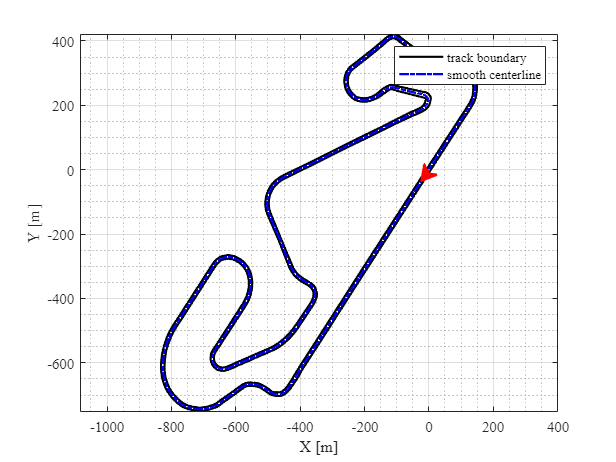

track = readtable(track_path, 'PreserveVariableNames',true);


ds_interp = 3;
[track_interp, s_interp] = calc_track_interp(table2array([track; track(1,:)]), ds_interp);

w_reserve = veh.wt/2 + veh.ws;
lb = -track_interp(:,3) + w_reserve;
ub =  track_interp(:,4) - w_reserve;

n_bnd = [lb ub];
n_bnd(1,:) = [0 0];
n_bnd(end,:) = [0 0];

weight = track_smooth_params('smooth');

iter = 4;
[n_opt_total, track_opt] = calc_track_smooth(track_interp, n_bnd, weight, iter);

preview_length = 0;
preview_points = fix(preview_length/ds_interp) + 1;
track_opt = [track_opt; track_opt(1:preview_points,:)];

[s_opt, ds_opt] = calc_length_xy(track_opt(:,1:2));
[phi_opt, kappa_opt] = calc_head_curv_num(track_opt(:,1:2));
[track_bnd_r, track_bnd_l] = calc_track_bnd(track_opt);

figure
plot(track_bnd_r(:,1),track_bnd_r(:,2),'k'), hold on, grid on
plot(track_bnd_l(:,1),track_bnd_l(:,2),'k')
plot(track_opt(:,1),track_opt(:,2),'b-.')
axis equal

% drawArrow
ha = annotation('arrow');  % store the arrow information in ha
ha.Parent = gca;           % associate the arrow the the current axes
ha.X = [track_opt(1,1) track_opt(15,1)];          % the location in data units
ha.Y = [track_opt(1,2) track_opt(15,2)];   
ha.LineWidth  = 2;          % make the arrow bolder for the picture
ha.HeadWidth  = 15;
ha.HeadLength = 10;
ha.Color = 'r';

xlabel('X [m]'), ylabel('Y [m]'), legend('track boundary','','smooth centerline')

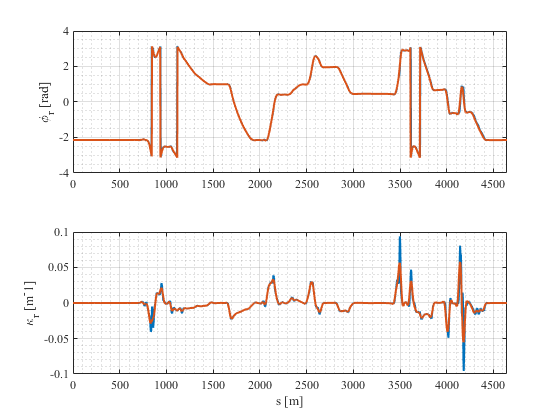

track_smooth = array2table([track_opt s_opt phi_opt kappa_opt]);
track_smooth.Properties.VariableNames = {'x','y','wr','wl','s','phi','kappa'};

if ~exist(fullfile(pwd,'tracks_smooth'), 'dir')
   mkdir('tracks_smooth')
end
writetable(track_smooth,['tracks_smooth/' track_name '_smooth' '.csv'])

%
[phi, kappa] = calc_head_curv_num(track_interp(:,1:2));

figure
tiledlayout(2,1)
nexttile
plot(s_interp,phi), hold on, grid on
plot(s_opt,phi_opt)
ylabel('\phi_r [rad]')
xlim([0 s_opt(end)])
nexttile
plot(s_interp,kappa), hold on, grid on
plot(s_opt,kappa_opt,'LineWidth',1.5)
ylabel('\kappa_r [m^-1]')
xlim([0 s_opt(end)])
xlabel('s [m]')

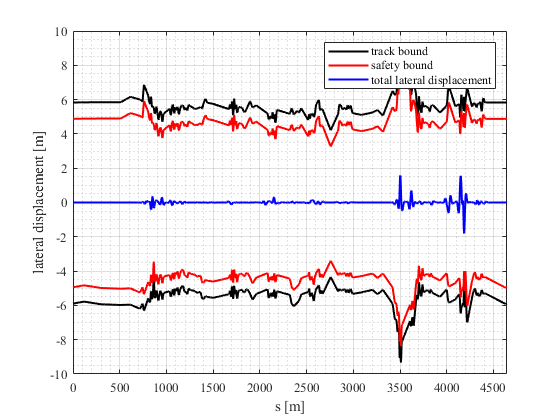

figure
plot(s_interp, [-track_interp(:,3), track_interp(:,4)],'k'), hold on, grid on
plot(s_interp, [lb ub],'r')
plot(s_interp, n_opt_total,'b')
xlim([0 s_opt(end)])
xlabel('s [m]'), ylabel('lateral displacement [m]')
legend('track bound','','safety bound','','total lateral displacement')

## B. Trajectory Optimization

import casadi.*

track = readtable(['tracks_smooth\' track_name '_smooth.csv']);

run('tro_code.m')


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:   590526
Number of nonzeros in inequality constraint Jacobian.:   124077
Number of nonzeros in Lagrangian Hessian.............:   477410

Total number of variables............................:    63564
                     variables with only lower bounds:        0
                variables with lower and upper bounds:    63564
                     variables with only upper bounds:        0
Total number of equa

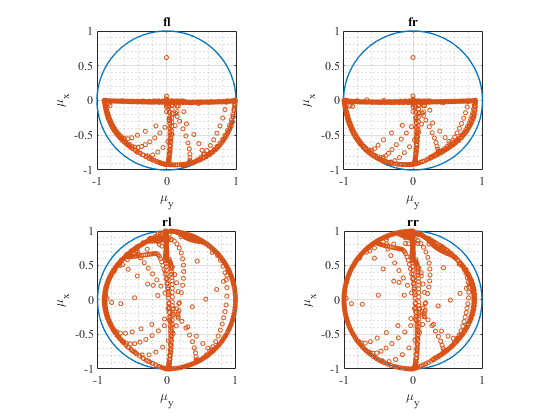

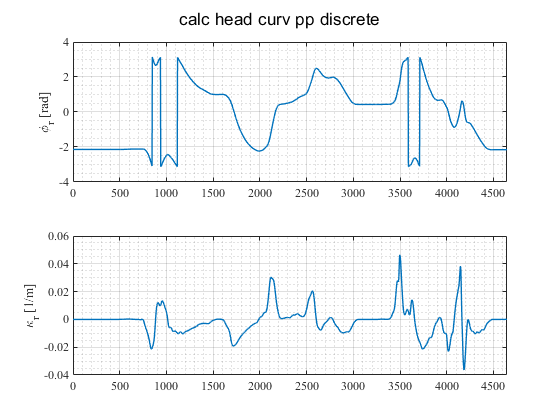

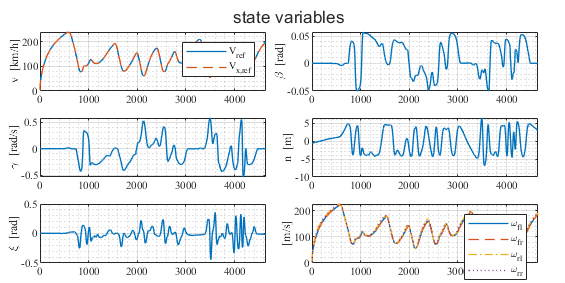

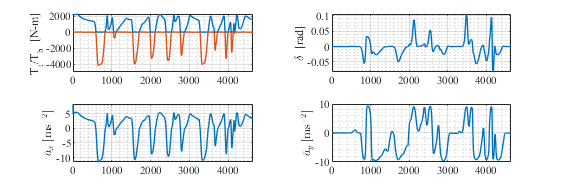

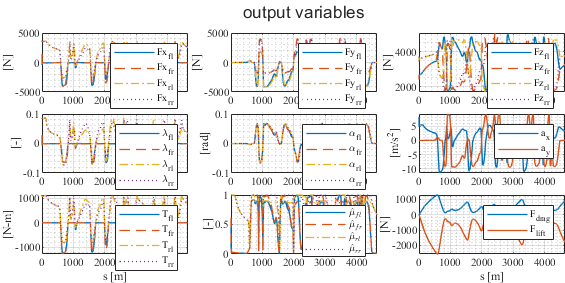

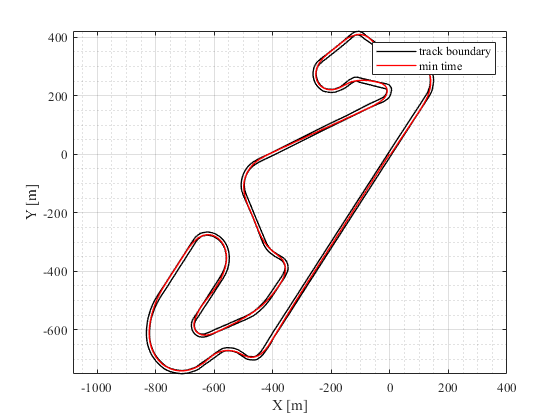

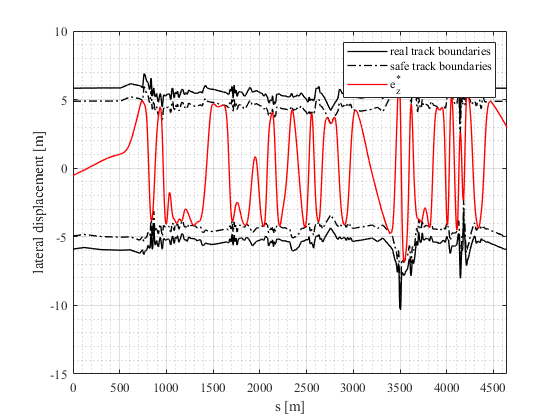

tro_plot_results

## 3. Track Post-Smoothing

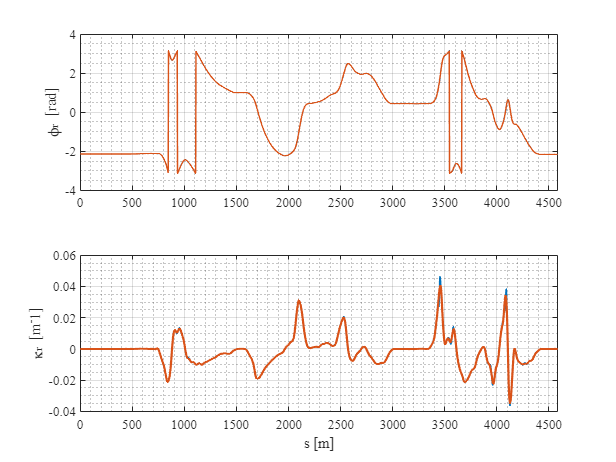

racetrack = readtable(['tracks_mintime\' track_name '_mintime' '.csv']);
racetrack = table2array(racetrack);

w_reserve = veh.wt/2 + veh.ws;
lb = -racetrack(:,3) + w_reserve;
ub =  racetrack(:,4) - w_reserve;

n_bnd = [lb ub];
n_bnd(1,:) = [0 0];
n_bnd(end,:) = [0 0];

weight = smooth_params('smooth');

iter = 4;
[n_opt_total, raceline_opt] = calc_track_smooth(racetrack, n_bnd, weight, iter);
[s, ~] = calc_length_xy(raceline_opt(:,1:2));
[phi, kappa] = calc_head_curv_num(raceline_opt(:,1:2));
[raceline_bnd_r, raceline_bnd_l] = calc_track_bnd(raceline_opt);

figure
tiledlayout(2,1)
nexttile
plot(racetrack(:,5),racetrack(:,6)), hold on, grid on
plot(s,phi)
ylabel('\phi_r [rad]')
xlim([0 s_opt(end)])
nexttile
plot(racetrack(:,5),racetrack(:,7)), hold on, grid on
plot(s,kappa,'LineWidth',1.5)
ylabel('\kappa_r [m^-1]')
xlim([0 s_opt(end)])
xlabel('s [m]')

% ds_racetrack = 0.5;
ds_racetrack = 1.0;
[raceline_smooth_interp, s_interp] = calc_track_interp(raceline_opt, ds_racetrack);
v_interp = spline(s,racetrack(:,end),s_interp);

[phi_interp, kappa_interp] = calc_head_curv_num(raceline_smooth_interp(:,1:2));
[track_bnd_r_interp, track_bnd_l_interp] = calc_track_bnd(raceline_smooth_interp);

figure
plot(track_bnd_r_interp(:,1),track_bnd_r_interp(:,2),'k'), hold on, grid on
plot(track_bnd_l_interp(:,1),track_bnd_l_interp(:,2),'k')
plot(raceline_smooth_interp(:,1),raceline_smooth_interp(:,2),'b-.')
index_max = calc_stop_flag(raceline_smooth_interp)

index_max = 4585

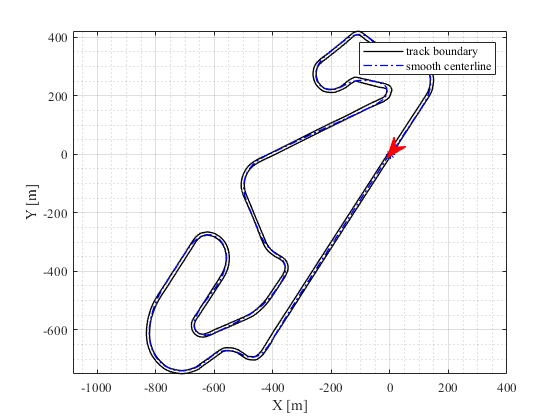

scatter(raceline_smooth_interp(index_max,1),raceline_smooth_interp(index_max,2),40,'*b')

axis equal

% drawArrow
ha = annotation('arrow');  % store the arrow information in ha
ha.Parent = gca;           % associate the arrow the the current axes
ha.X = [raceline_smooth_interp(1,1) raceline_smooth_interp(15,1)];          % the location in data units
ha.Y = [raceline_smooth_interp(1,2) raceline_smooth_interp(15,2)];   
ha.LineWidth  = 2;          % make the arrow bolder for the picture
ha.HeadWidth  = 15;
ha.HeadLength = 15;
ha.Color = 'r';

xlabel('X [m]'), ylabel('Y [m]'), legend('track boundary','','smooth centerline')

racetrack_interp = array2table([raceline_smooth_interp s_interp phi_interp kappa_interp v_interp]);
racetrack_interp.Properties.VariableNames = {'x','y','wr','wl','s','phi','kappa','v'};

if ~exist(fullfile(pwd,'tracks_race'), 'dir')
   mkdir('tracks_race')
end
writetable(racetrack_interp,['tracks_race\' track_name '_race' '.csv'])

xr = racetrack_interp.x;
yr = racetrack_interp.y;
wr = racetrack_interp.wr;
wl = racetrack_interp.wl;
sr = racetrack_interp.s;
phir = racetrack_interp.phi;
kappar = racetrack_interp.kappa;
vr = racetrack_interp.v;

save(['tracks_preload\' 'preload_' track_name],'xr','yr','wr','wl','sr','phir','kappar','vr','index_max')
